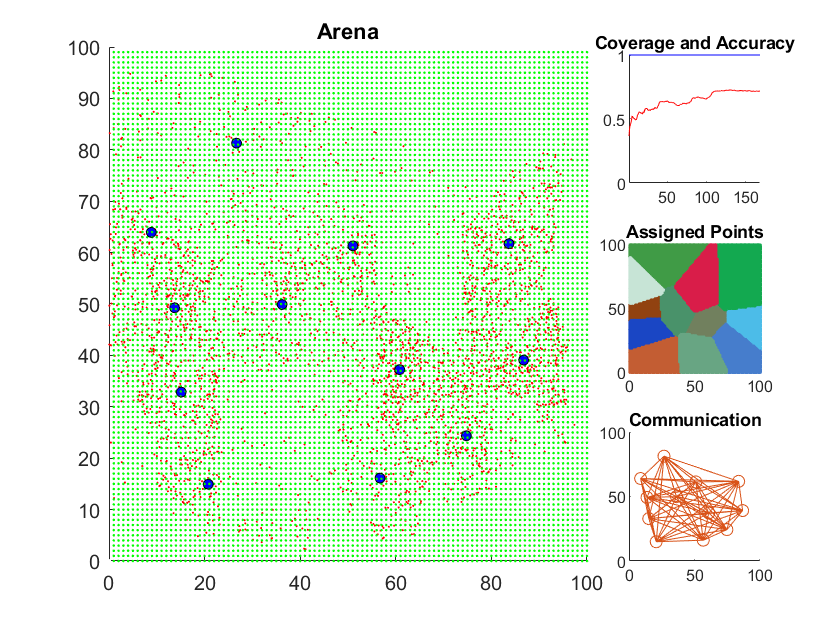

sides = 100;
partition = 1;
rObs = 80;
rComm = rObs*2;
agentNum = randi([8,12]);
agentNum = 12;

velocity = (1.6 * sqrt(2) / 2); %0.4 = 10 km/h

delay = 0;

duration = 168; %1 = 1 hour
dt = 1;

% Options
showCoverage = true;
showCentroids = true;
showTrajectory = false;
showInitialPos = false;
graphByGrid = false; % Warning! Only good for smaller or fixed-density arenas!
fixedArena = false;
graphByGridScale = 1;
dotSize = 25;
coverageBrightness = 0.15;

D = randi([0,0], sides, sides);
if (fixedArena == true)
    for i = 1:duration
        D = calcDensity(D, 0.01, sides, 1);
    end
end

vColor = cell(agentNum,1);
for i = 1:agentNum
    vColor{i} = [rand rand rand];
end

agentPos = randi([20, 80], agentNum, 2);
agentPosArr = cell(duration,1);
agentPosArr{1} = agentPos;

if (showInitialPos == true)
    initialAgentPos = agentPos;
end

for n = 1:dt:duration
    if (fixedArena == false)
        D = calcDensity(D, 0.01, sides, 1);
    end
    % Initial points assignment
    if (graphByGrid == false)
        x=sides-(0+rand(1,D(1,1))*(1-0));
        y=0+rand(1,D(1,1))*(1-0);
        for i = 1:sides
            for j = 1:sides
                xN = sides-((i-1)+rand(1,D(i,j))*(i-(i-1)));
                yN = (j-1)+rand(1,D(i,j))*(j-(j-1));
                x = horzcat(x, xN);
                y = horzcat(y, yN);
            end
        end
    end
    % Bin the data:
    pts = linspace(0, sides, sides);
    % Plot data:
    subplot(3,4,[1,11]);
    scatter(0,0,'w.');
    hold on;
    if (graphByGrid == false)
        scatter(y, x, 10, 'r.');
    else
        for i = 1:sides
            for j = 1:sides
                if (D(i,j) > 0)
                    scatter(j,sides-i,D(i,j)*graphByGridScale,'r','filled');
                else
                    continue;
                end
            end
        end
    end
    set(gca, 'XLim', pts([1 end]), 'YLim', pts([1 end]));

    [commCells, adjMatrix] = communication(agentPos, rComm);

    if (showInitialPos == true)
        if (showCoverage == false)
            for i = 1:agentNum
                scatter(initialAgentPos(i,2),sides-initialAgentPos(i,1),'Marker','o','MarkerEdgeColor',vColor{i});
            end
        else
            scatter(initialAgentPos(:,2),sides-initialAgentPos(:,1),'mo');
        end
    end

    if (showCoverage == false)
        for i = 1:agentNum
            scatter(agentPos(i,2),sides-agentPos(i,1),dotSize,vColor{i},'filled');
        end
    else
        scatter(agentPos(:,2),sides-agentPos(:,1),dotSize,'b','filled');
    end

    agentPoints = assignAgentPoints(agentPos, commCells, sides, partition, rObs);
    if (showCoverage == true)
        for i = 1:agentNum
            scatter(agentPoints{i}(:,2), sides-agentPoints{i}(:,1), coverageBrightness*100,'g.');
        end
    end

    mass = calcMass(agentPoints,D,1);
    centroids = calcCentroids(agentPoints,mass,D,agentPos,1);
    if (showCentroids == true)
        for i = 1:agentNum
            scatter(centroids(i,2), sides-centroids(i,1), dotSize, 'ko');
        end
    end

    if (showTrajectory == true && n > 1)
        agentPosArr{n} = agentPos;
        for i = 1:agentNum
            for j = 2:n
                prevX = agentPosArr{j-1}(i,2);
                prevY = sides-agentPosArr{j-1}(i,1);
                currX = agentPosArr{j}(i,2);
                currY = sides-agentPosArr{j}(i,1);
                if (showCoverage == false)
                    plot([prevX,currX],[prevY,currY],'LineStyle','--','Color',vColor{i});
                else
                    plot([prevX,currX],[prevY,currY],'LineStyle','--','Color','m');
                end
            end
        end
    end

    title('Arena');
    hold off;

    [agentPos, distanceTravelled, energy] = moveAgents(agentPos, centroids, sides, dt, 1, "Fixed", velocity, 1);
    agentPoints = assignAgentPoints(agentPos, commCells, sides, partition, rObs);

    % Coverage and Accuracy Graph
    subplot(3,4,4);
    hold on;
    title('Coverage and Accuracy');
    set(gca, 'XLim', [1 duration], 'YLim', [0 1]);
    coverage(n/dt) = calcCoverage(agentPoints,partition,D,sum(sum(D)));
    plot(coverage(1:n/dt),'b-');
    accuracy = 0;
    for i = 1:agentNum
        accuracy = accuracy + (abs(mass(i) - (sum(sum(D)) / agentNum))) / (sum(sum(D)) / agentNum);
    end
    accuracyArr(n/dt) = 1 - accuracy / agentNum;
    plot(accuracyArr(1:n/dt),'r-');

    hold off;

    % Assigned Points Graph
    subplot(3,4,8);
    scatter(0,0,'w.');
    hold on;
    title('Assigned Points');
    set(gca, 'XLim', pts([1 end]), 'YLim', pts([1 end]));
    for i = 1:agentNum
        scatter(agentPoints{i}(:,2), sides-agentPoints{i}(:,1), 'Marker', '.', 'MarkerEdgeColor',vColor{i}, ...
    'MarkerFaceColor',vColor{i});
    end
    hold off;

    % Communication Graph
    subplot(3,4,12);
    scatter(agentPos(:,2),sides-agentPos(:,1),'Marker','o', 'MarkerEdgeColor', [0.8500 0.3250 0.0980]);
    hold on;
    title('Communication');
    set(gca, 'XLim', pts([1 end]), 'YLim', pts([1 end]));

    for i = 1:size(commCells,2)
        for j = 1:size(commCells{i},1)
%         if (size(commCells{i},1) == 1)
%             continue;
%         end
            targetNum = commCells{i}(j);
            targetX = agentPos(targetNum,2);
            targetY = sides-agentPos(targetNum,1);
            selfX = agentPos(i,2);
            selfY = sides-agentPos(i,1);
            plot([selfX,targetX],[selfY,targetY],'Color', [0.8500 0.3250 0.0980]);
        end
    end
    hold off;
    
    pause(delay);
end


totalAccuracy = 0;
for i = 1:duration
    totalAccuracy = totalAccuracy + accuracyArr(i);
end
avgAccuracy = totalAccuracy / duration

avgAccuracy = 0.6479